# Actividad #4

- Nombre:

- Fecha:

- Reposiroty: [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

- Refrence: [https://github.com/vasanza/Matlab_Code/tree/main](https://github.com/vasanza/Matlab_Code/tree/main)

Objetivos:

- Automatizar la copia del repositorio

- Actualizar el current folder en el lugar de trabajo

Paso 1: Respaldar en una carpeta personal la Actividad

clear % Borrar variables en el workspace y libera memoria RAM
clc % Limpia el Command Window

% Mombre de la carpeta de la Actividad en el repositorio
raiz = cd;
partes = split(raiz, '\');
nombreCarpeta = partes{end} % Nombre de la carpeta

nombreCarpeta = 'ACTIVIDAD4'

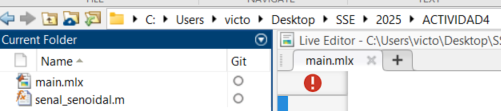

MiRespaldo = 'C:\Users\victo\Desktop\SSE_vic'; %<=========
Repositorio = 'C:\Users\victo\Desktop\SSE\2025'; %<=========
if true
    origen = cd;
    destino = fullfile(MiRespaldo, nombreCarpeta);         % Ruta completa a la carpeta destino
    if exist(destino, 'dir') && ~isempty(dir(fullfile(destino, '*')))
        warning('La carpeta "%s" ya existe y no está vacía. No se copió nada.', destino);
    else
        copyfile(origen, destino)                  % Copiar la carpeta
        fprintf('Copia completada en: %s\n', destino);
    end
    cd(fullfile(MiRespaldo,nombreCarpeta))
    edit('main')
else
    % Regresar al repositorio
    cd(fullfile(Repositorio,nombreCarpeta))
end

Paso 2: Crear un codigo basico

% Parámetros
f = 10;         % Frecuencia de la señal en Hz
A1 = 3;          % Amplitud1
A2 = 16;          % Amplitud1
fase1 = 0;      % Fase1
fase2 = 10;     % Fase2
T = 0.25;          % Duración en segundos
fsmin = f*2;    % Frecuencia de muestreo minima (Nyquist-Shannon)
fs = 620;      % Frecuencia de muestreo en Hz

Documentacion de la senal senoidal

help senal_senoidal

  --- SEÑAL SENOIDAL ---
 function [y] = senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
 
  Parámetros:
  f = 10;         % Frecuencia en Hz
  A = 1;          % Amplitud
  fase1 = 0; fase2 = 10;        % Fase
  T = 1;          % Duración en segundos
  fs = 1000;      % Frecuencia de muestreo en Hz



% Usamos la funcion: senal_senoidal(frecuencia,amplitud,fase,tiempo,fs)
y1 = senal_senoidal(f,A1,fase1,T,fs);
y2 = senal_senoidal(f,A2,fase2,T,fs);

Paso 3: Mostrar resultados con plot

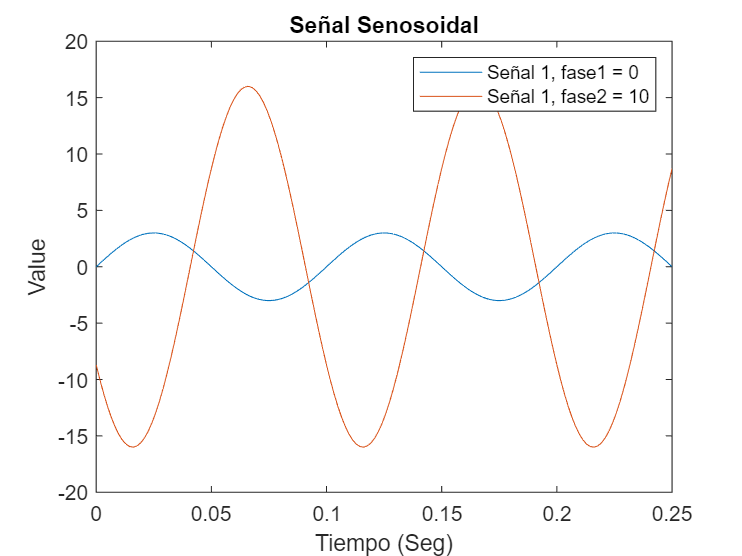

t = 0:1/fs:T;
figure
plot(t,y1) %Señal 1
hold on
plot(t,y2) %Señal 2
title("Señal Senosoidal")
xlabel("Tiempo (Seg)")
ylabel("Value")
legend("Señal 1, fase1 = 0", "Señal 1, fase2 = 10")